clear all
%Assign parameters
SIR_num = [99,1]';%population distribution
population = sum(SIR_num);
SIR_initial = SIR_num;

deltaT = 0.1;%time step
tTotal = 100000;%total modelling time
beta = 0.01/100;%infection rate

lambda = 0.017/365;%birth rate
ds = 0.0079/365;%natrual death
b = 0.1;
%c = 0.0079/365;
p=0.1;

colorCode = ["#77AC30", "#FF0000", "#0000FF"];


%Predict using RK4
t = zeros(1,tTotal/deltaT+1);
t(1) = 0; %start with 0 day
SIR_RK = zeros(length(SIR_initial),tTotal/deltaT+1);
SIR_RK(:,1) = SIR_initial;
n = 1;

while t(n)<= tTotal
    SIR_RK(:,n+1) = SIR_VAM_RK4(deltaT,SIR_RK(:,n),lambda,beta,b,p,ds);
    t(n+1) = t(n) + deltaT;
    n = n + 1;
end

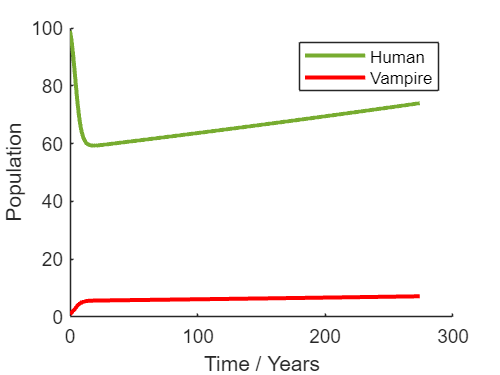

%Plot RK4
sizeSIR = size(SIR_RK);
numVar = sizeSIR(1);

for i  = 1:numVar
    hold on
    plot(t/365,SIR_RK(i,:),'-',Color=colorCode(i),LineWidth=2)
end
hold off
xlabel('Time / Years')
ylabel('Population')
legend('Human','Vampire',Location='northeast')

%ylim([0,200])

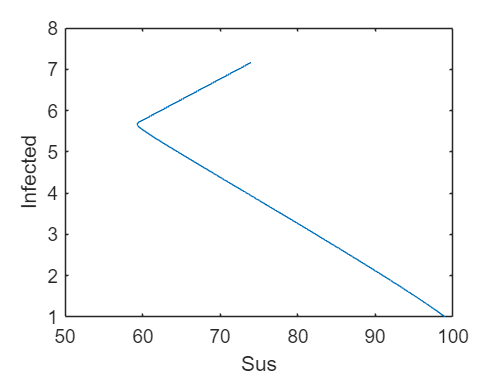


plot(SIR_RK(1,:),SIR_RK(2,:))
xlabel('Sus')
ylabel('Infected')

%Solve equilibrium points
p = 0.1;
M = beta*SIR_num(1)/(lambda-ds);
N = beta*b*SIR_num(1)/(lambda-ds);
O = ds / ((lambda-ds)*p);
initial_guess = [1; 0.1];
equations = @(x) [1 - M * x(2) * (1 - x(2) / (p * x(1)));N * x(1) * (1 - x(2) / (p * x(1))) - O * x(2)];
solution = fsolve(equations, initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>
